# RobotTugFSM.mlx is a hardware-in-the-loop simulation of a robot tug

This code controls an autonomous robot boat through a simulated mission in theLPB water testing tank.

The fundamental difference between a control system and a robotic system is that control systems do not 'think' about what to do next. Given on set of inputs, it will always generate the same out.put A robot system will take that same set of inputs, consider multiple responses and choose the best output to accomplish the mission. This script will give you hands-on experience with a **classical pure-pursuit control system**, then its sister program **RobotTugThinkLab** will perform the same mission with a behavior-based robot controller that blends multiple synchronous robot behaviors to more robustly accomplish thte same goal.

Written (pair programmed) by CJ Hilty and Ben Morris 2022. Rev A.

close all; % close any open figure windows
clc     % clear command window
clear   % clear MATLAB workspace

### **Set up robot control system** (code that runs once)

Set up the Raspberry Pi to control the tug. Call **TugRaspPiSetup **function to create and configure the Pi. 

make sure you have the **TugRaspPiSetup** function in the local directory

disp("Downloading code to Raspberry Pi may take about 10 seconds.")

[~,rudderServo,propServo, ttServo, blinkLED, camera] = TugRaspPiSetup_RevB();

make sure you have the **TestPool.png** image in the local directory.

img=imread('TestPool.png');             % load test pool image (from local directory)
grayimage=im2gray(img);                 % convert to grayscale
bwimage=grayimage < 0.5;                % convert to black and white
MapOfOval = binaryOccupancyMap(bwimage,10); % convert to a binary occupancy map in meters
% show(MapOfPool);                      % show map

%Inflate map so robot can be treated as a point.
%Assume robot is 0.25m square.
MapOfPoolInflated = copy(MapOfOval);    % make a copy without overwriting original data
inflate(MapOfPoolInflated,0.25);        % dilate the map to accommodate robot size

% To prevent unexpected display glitches in the livescript window,
% create a free-floating figure for the maps to display simulation updates
testPool = figure('name','testPool','NumberTitle','off','Visible','on');
figure(testPool);                      % go to testPool figure for next plot
    show(MapOfPoolInflated)             % show new map in a figure window
    grid on; grid minor;                % set plot properties

Create an IR-based map of the world that will be filled as the Rover drives around the Oval

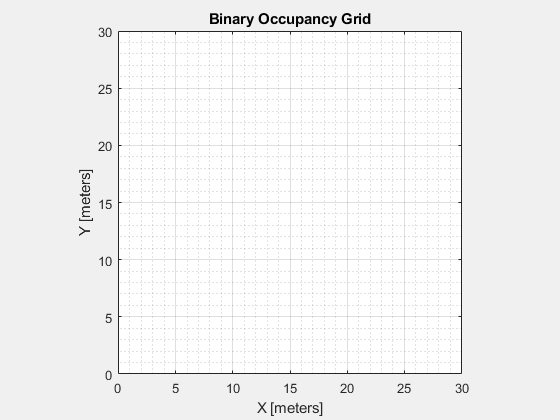

% Create an empty map of the same dimensions as the test pool occupancy map
[mapdimx,mapdimy] = size(bwimage);      % find and store size of map
sharpIRmap = binaryOccupancyMap(mapdimx,mapdimy,10,'grid');% make empty map of same size

% create another free-floating figure for map updates to avoid livescript display glitches
tugSharpIRScan = figure('name','TugSharpIRScan','NumberTitle','off','Visible','on');
figure(tugSharpIRScan);
    show(sharpIRmap);                   % display the figure
    grid on; grid minor;                % set grid options


% note: map figure should be blank to start and it will be populated later.

Create a simulated differential drive robot rover. Inputs are robot vehicle speed and heading.

diffDriveTug = differentialDriveKinematics('vehicleInputs','VehicleSpeedHeadingRate');

Create a pure pursuit Tug controller (this controller generates the required speed and heading values needed to follow a path. It can incorporate a desired linear velocity (m/s) and maximum angular velocity (radians/sec)

TugController = controllerPurePursuit('DesiredLinearVelocity',2,'MaxAngularVelocity',3);

Create a simulated 180° sharp IR range sensor for the Tug. It should have a **max range of 10 meters**.

- The sensor simulates readings for a given pose on a map. In this case, it will be the Olin pool.

- The rangeSensor function has scarce documentation. On the function right-click> help or f1 is useful.

- The simulated IR will simulate range readings from an IR based on position and location on a map.

sharpIRPod = rangeSensor;        % create a simulated rangeSensor object
sharpIRPod.Range = [0.1,10];     % set minimum and maximum range of sensor
sharpIRPod.HorizontalAngle = [-pi/2, pi/2]      % sets each sensor's detection angle

sharpIRPod =   rangeSensor with properties:

                        Range: [0.1000 10]
              HorizontalAngle: [-1.5708 1.5708]
    HorizontalAngleResolution: 0.0244
                   RangeNoise: 0
         HorizontalAngleNoise: 0
                  NumReadings: 129


sharpIRPod.HorizontalAngleResolution = 0.628318 % resolution that sizes 6 sensors to proper map viewing size

sharpIRPod =   rangeSensor with properties:

                        Range: [0.1000 10]
              HorizontalAngle: [-1.5708 1.5708]
    HorizontalAngleResolution: 0.6283
                   RangeNoise: 0
         HorizontalAngleNoise: 0
                  NumReadings: 6


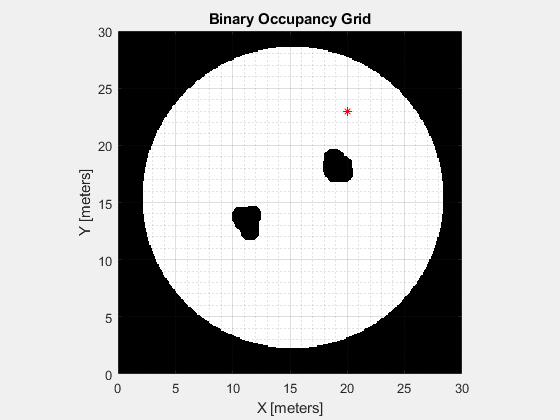

testPose = [20 20 pi/2];    % set an initial test position for IR

% Plot the test spot for the simulated IR scan on the test pool occupancy map
figure(testPool)           % select the testPool map figure for drawing
hold on;
plot(20,23, 'r*');          %plot robot position in pool
hold off;

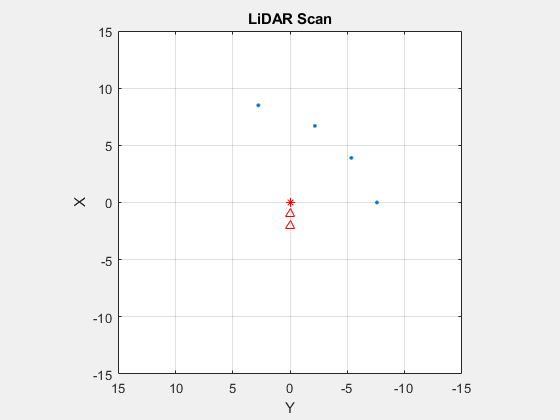


% Generate a IR test scan from the test position defined above in testPose
    [ranges,angles] = sharpIRPod(testPose, MapOfPoolInflated);
    scan = lidarScan(ranges, angles);

% Visualize the test IR scan from the robot's coordinate system
% by creating a new free-standing figure with the robot at the center
% and plotting the local IR scan on that figure.
    localSharpIRPlot = figure('Name','localSharpIRMap','NumberTitle','off','Visible','on');
    figure(localSharpIRPlot);
    plot(scan);
    axis([-15 15 -15 15])
    hold on;
    plot(0,0,'r*');     % plot robot position
    plot(-1,0,'r^');    % plot robot position
    plot(-2,0,'r^');    % plot robot position
    hold off;    

Set up a Narwhal Cam Figure

narwhalCamFigure = figure("Name", "Narwhal Cam", "NumberTitle", "off", "Visible", "on");

Path variables (unused)

    % path = [20 23; 15 23; 10 23; 5 15; 10 10; 15 10; 25 15];    % clear path waypoints
%path = [20 23; 15 23; 10 23; 5 15; 15 12; 20 10; 25 15]    % collision waypoints
%path = [20 20; 25 25]; % short matrix of waypoints to test stopping precision
% Plot the waypoints as a path on the OlinOvalMap occupancy map
% figure(testPool);                          % select the testPool figure
% hold on;
% plot(path(:,1),path(:,2),'o-');             % Plot the points from the matrix of waypoints
% hold off;

Use the waypoints in the **path** variable as the waypoints the Pure Pursuit controller will follow

% TugController.Waypoints = path;       %Set rover waypoints

Create a free floating figure for robot behavior brainwave display

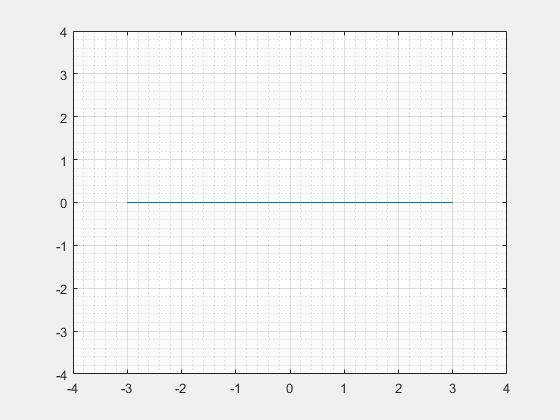

numWaves = 7;
brainWaves = figure('name', 'Behavior Brain Waves', 'NumberTitle','off', 'Visible','on');
figure(brainWaves);
pbrain = plot(linspace(-3, 3, numWaves), zeros(1, numWaves));
axis([-4 4 -4 4]);
grid on;
grid minor;

Set the initial pose and final goalWayPoint location from points in the **path** variable, then create global variables for storing the current pose and an index for tracking loop count.

initTugPose = [20, 23, pi/2]; % Store initial location and orientation, aka pose
%goalWayPoint = [25, 15]';  % Sets target end waypoint. Using this is doom.
sampleTime = 0.75;                          % Sample time (seconds)
t = 0:sampleTime:100;                       % Time array
robotPoses = zeros(3,length(t));            % Preallocate arrray for robot Poses
robotPoses(:,1) = initTugPose';           % Add initial robot pose to robot Poses array
r = rateControl(1/sampleTime);
reset(r);
tolerance = 0.1;                            % In meters, the minimum distance from the final waypoint to finish routine

Create variables for the control loop

controlIndex = 1;                           % creates a loop control to limit number of total loops
behaviorCycleTime = 0;                      % create a resetable behavior clock
followClock = 0;                            % create a whale following clock
vLook = zeros(1, numWaves);                 % create look for narwhal vel vector
wLook = zeros(1, numWaves);                 % create look for narwhal w vector
vChase = zeros(1, numWaves);                % create chase narwhal vel vector
wChase = zeros(1, numWaves);                % create chase narwhal w vector
vAvoid = zeros(1, numWaves);                % create avoid behavior vel vector
wAvoid = zeros(1, numWaves);                % create avoid behavior w vector
legTime = 20;                               % create legtime variable that will be randomized later
vRef = 0;                                   % initial tug velocity
wRef = 0;                                   % initial tug rotation rate
searchDirection = rand();                   % initial 'left or right' determination for search mode

Arrange figure windows for easy viewing, ask the operator if they are ready and give start options

iptwindowalign(testPool,'right',tugSharpIRScan,'left')

iptwindowalign(tugSharpIRScan,'bottom',localSharpIRPlot,'top');
iptwindowalign(testPool,'right',localSharpIRPlot,'left');

iptwindowalign(narwhalCamFigure,'right',localSharpIRPlot,'left');
iptwindowalign(testPool,'bottom',narwhalCamFigure,'top');
iptwindowalign(testPool,'left',brainWaves,'right')

runRover = input('Press CTRL + C to abort, or\nWhen ready, press 1 and then ENTER to run tug.\n')

runRover = 1

### **Run robot control loop **(code that runs over and over)

X-pixel value: 538.8359 
Y-pixel value: 696.9424 


Elapsed time is 0.638188 seconds.


X-pixel value: 538.4531 
Y-pixel value: 697.5639 


Elapsed time is 0.573815 seconds.


X-pixel value: 41.0168 
Y-pixel value: 394.7171 


Elapsed time is 0.500782 seconds.


X-pixel value: 44.2266 
Y-pixel value: 394.9728 


Elapsed time is 0.491124 seconds.


X-pixel value: 47.0854 
Y-pixel value: 394.9543 


Elapsed time is 0.504248 seconds.


X-pixel value: 227.2891 
Y-pixel value: 387.6976 


Elapsed time is 0.507739 seconds.


X-pixel value: 21.3466 
Y-pixel value: 449.5535 


Elapsed time is 0.487063 seconds.


X-pixel value: 146.7863 
Y-pixel value: 456.1746 


Elapsed time is 0.495359 seconds.


X-pixel value: 240.8805 
Y-pixel value: 461.7170 


Elapsed time is 0.505783 seconds.


X-pixel value: 240.3038 
Y-pixel value: 458.2430 


Elapsed time is 0.498816 seconds.


X-pixel value: 481.4323 
Y-pixel value: 379.0113 


Elapsed time is 0.532824 seconds.


X-pixel value: 481.1022 
Y-pixel value: 379.1022 


Elapsed time is 0.684530 seconds.


X-pixel value: 480.6929 
Y-pixel value: 379.1571 


Elapsed time is 0.725813 seconds.


X-pixel value: 480.0319 
Y-pixel value: 378.7305 


Elapsed time is 1.003045 seconds.


X-pixel value: 481.4630 
Y-pixel value: 379.2724 


Elapsed time is 0.689181 seconds.


X-pixel value: 480.6932 
Y-pixel value: 378.8977 


Elapsed time is 0.580822 seconds.


X-pixel value: 262.8382 
Y-pixel value: 458.7120 


Elapsed time is 0.504536 seconds.


X-pixel value: 452.5401 
Y-pixel value: 437.3816 


Elapsed time is 0.492635 seconds.


X-pixel value: 553.0385 
Y-pixel value: 437.2013 


Elapsed time is 0.525483 seconds.


X-pixel value: 553.4594 
Y-pixel value: 437.4576 


Elapsed time is 0.522280 seconds.


X-pixel value: 553.3673 
Y-pixel value: 439.0334 


Elapsed time is 0.505877 seconds.


X-pixel value: 553.5262 
Y-pixel value: 435.9096 


Elapsed time is 0.498981 seconds.


X-pixel value: 534.9270 
Y-pixel value: 437.3595 


Elapsed time is 0.493638 seconds.


X-pixel value: 534.3870 
Y-pixel value: 437.2750 


Elapsed time is 0.514303 seconds.


X-pixel value: 553.0944 
Y-pixel value: 436.4418 


Elapsed time is 0.496084 seconds.


X-pixel value: 534.3886 
Y-pixel value: 432.9921 


Elapsed time is 0.551212 seconds.


X-pixel value: 553.3129 
Y-pixel value: 437.1937 


Elapsed time is 0.496468 seconds.


X-pixel value: 553.5019 
Y-pixel value: 437.6208 


Elapsed time is 0.504885 seconds.


X-pixel value: 613.0736 
Y-pixel value: 440.4110 


Elapsed time is 0.506559 seconds.


X-pixel value: 686.1447 
Y-pixel value: 438.7237 


Elapsed time is 0.501352 seconds.


X-pixel value: 684.2071 
Y-pixel value: 433.9210 


Elapsed time is 0.510648 seconds.


X-pixel value: 683.7107 
Y-pixel value: 436.3237 


Elapsed time is 0.495956 seconds.


X-pixel value: 684.3489 
Y-pixel value: 434.4611 


Elapsed time is 0.505096 seconds.


X-pixel value: 684.4297 
Y-pixel value: 434.4813 


Elapsed time is 0.511942 seconds.


X-pixel value: 682.9799 
Y-pixel value: 438.3779 


Elapsed time is 0.507152 seconds.


X-pixel value: 676.4189 
Y-pixel value: 433.3159 


Elapsed time is 0.526330 seconds.


X-pixel value: 683.9910 
Y-pixel value: 433.9216 


Elapsed time is 0.497111 seconds.


X-pixel value: 684.3450 
Y-pixel value: 434.0382 


Elapsed time is 0.498931 seconds.


X-pixel value: 684.3413 
Y-pixel value: 434.9450 


Elapsed time is 0.498155 seconds.


X-pixel value: 684.3876 
Y-pixel value: 433.4939 


Elapsed time is 0.498979 seconds.


X-pixel value: 739.6573 
Y-pixel value: 435.2808 


Elapsed time is 0.499053 seconds.


X-pixel value: 48.5664 
Y-pixel value: 317.2647 


Elapsed time is 0.504591 seconds.


X-pixel value: 49.9409 
Y-pixel value: 317.8934 


Elapsed time is 0.571835 seconds.


X-pixel value: 50.7341 
Y-pixel value: 316.1803 


Elapsed time is 0.502953 seconds.


X-pixel value: 53.0225 
Y-pixel value: 320.7648 


Elapsed time is 0.508273 seconds.


X-pixel value: 168.3827 
Y-pixel value: 314.8930 


Elapsed time is 0.519579 seconds.


X-pixel value: 275.4027 
Y-pixel value: 296.4213 


Elapsed time is 0.495922 seconds.


X-pixel value: 281.9559 
Y-pixel value: 293.6236 


Elapsed time is 0.509766 seconds.


X-pixel value: 400.5052 
Y-pixel value: 293.0109 


Elapsed time is 0.523420 seconds.


X-pixel value: 448.9922 
Y-pixel value: 288.7555 


Elapsed time is 0.513237 seconds.


X-pixel value: 524.0684 
Y-pixel value: 308.5860 


Elapsed time is 0.607754 seconds.


X-pixel value: 500.1796 
Y-pixel value: 328.8224 


Elapsed time is 0.553431 seconds.


X-pixel value: 364.3527 
Y-pixel value: 340.3275 


Elapsed time is 0.618295 seconds.


X-pixel value: 305.8247 
Y-pixel value: 318.1316 


Elapsed time is 0.657320 seconds.


X-pixel value: 304.4167 
Y-pixel value: 316.3473 


Elapsed time is 0.626473 seconds.


X-pixel value: 253.7188 
Y-pixel value: 332.6690 


Elapsed time is 0.675806 seconds.


X-pixel value: 241.8515 
Y-pixel value: 320.0008 


Elapsed time is 0.646130 seconds.


X-pixel value: 212.3924 
Y-pixel value: 318.5736 


Elapsed time is 0.638173 seconds.


X-pixel value: 151.5434 
Y-pixel value: 330.9636 


Elapsed time is 0.640033 seconds.


X-pixel value: 43.3378 
Y-pixel value: 329.3911 


Elapsed time is 0.642784 seconds.


X-pixel value: 197.5896 
Y-pixel value: 356.4400 


Elapsed time is 0.751159 seconds.


X-pixel value: 67.9699 
Y-pixel value: 318.8205 


Elapsed time is 0.768886 seconds.


X-pixel value: 397.0483 
Y-pixel value: 358.5316 


Elapsed time is 0.671486 seconds.


X-pixel value: 239.3334 
Y-pixel value: 305.4240 


Elapsed time is 0.625078 seconds.


X-pixel value: 232.9055 
Y-pixel value: 304.8652 


Elapsed time is 0.699666 seconds.


X-pixel value: 231.2402 
Y-pixel value: 303.9527 


Elapsed time is 0.693631 seconds.


X-pixel value: 227.8250 
Y-pixel value: 305.9672 


Elapsed time is 0.700699 seconds.


X-pixel value: 215.8514 
Y-pixel value: 304.8846 


Elapsed time is 0.673923 seconds.


X-pixel value: 57.4630 
Y-pixel value: 291.2054 


Elapsed time is 0.771569 seconds.


X-pixel value: 92.9346 
Y-pixel value: 297.2897 


Elapsed time is 0.648429 seconds.


X-pixel value: 111.6990 
Y-pixel value: 294.2633 


Elapsed time is 0.772845 seconds.


X-pixel value: 626.6987 
Y-pixel value: 209.2237 


Elapsed time is 0.565411 seconds.


X-pixel value: 662.4096 
Y-pixel value: 198.7661 


Elapsed time is 0.565755 seconds.


X-pixel value: 567.0972 
Y-pixel value: 154.6541 


Elapsed time is 0.550151 seconds.


X-pixel value: 561.9676 
Y-pixel value: 152.5839 


Elapsed time is 0.585431 seconds.


X-pixel value: 578.8277 
Y-pixel value: 177.4881 


Elapsed time is 0.551263 seconds.


X-pixel value: 576.9059 
Y-pixel value: 179.8372 


Elapsed time is 0.573004 seconds.


X-pixel value: 573.3334 
Y-pixel value: 180.6442 


Elapsed time is 0.543191 seconds.


X-pixel value: 572.7873 
Y-pixel value: 177.3124 


Elapsed time is 0.566465 seconds.


X-pixel value: 581.3609 
Y-pixel value: 196.0037 


Elapsed time is 0.543274 seconds.


X-pixel value: 579.6696 
Y-pixel value: 197.2485 


Elapsed time is 0.555154 seconds.


X-pixel value: 576.8201 
Y-pixel value: 198.9752 


Elapsed time is 0.574250 seconds.


X-pixel value: 574.4350 
Y-pixel value: 197.8495 


Elapsed time is 0.583630 seconds.


X-pixel value: 570.3040 
Y-pixel value: 198.1376 


Elapsed time is 0.577757 seconds.


X-pixel value: 564.4615 
Y-pixel value: 207.5532 


Elapsed time is 0.550082 seconds.


X-pixel value: 453.5192 
Y-pixel value: 219.4548 


Elapsed time is 0.605334 seconds.


X-pixel value: 306.9995 
Y-pixel value: 221.7238 


Elapsed time is 0.530842 seconds.


X-pixel value: 303.4350 
Y-pixel value: 222.0047 


Elapsed time is 0.540911 seconds.


X-pixel value: 266.5076 
Y-pixel value: 237.3905 


Elapsed time is 0.569390 seconds.


X-pixel value: 251.2684 
Y-pixel value: 237.1275 


Elapsed time is 0.567696 seconds.


X-pixel value: 255.0513 
Y-pixel value: 246.9861 


Elapsed time is 0.679018 seconds.


X-pixel value: 252.2741 
Y-pixel value: 245.0059 


Elapsed time is 0.544744 seconds.


X-pixel value: 177.4733 
Y-pixel value: 251.4814 


Elapsed time is 0.669190 seconds.


X-pixel value: 139.7409 
Y-pixel value: 289.5496 


Elapsed time is 0.540974 seconds.


X-pixel value: 662.3634 
Y-pixel value: 434.5421 


Elapsed time is 0.519398 seconds.


X-pixel value: 479.3939 
Y-pixel value: 441.1694 


Elapsed time is 0.502158 seconds.


X-pixel value: 478.7028 
Y-pixel value: 444.6845 


Elapsed time is 0.532286 seconds.


X-pixel value: 479.1851 
Y-pixel value: 443.2511 


Elapsed time is 0.594787 seconds.


X-pixel value: 475.5736 
Y-pixel value: 443.0295 


Elapsed time is 0.558803 seconds.


X-pixel value: 362.9071 
Y-pixel value: 457.7555 


Elapsed time is 0.518078 seconds.


X-pixel value: 358.0683 
Y-pixel value: 446.6503 


Elapsed time is 0.575442 seconds.


X-pixel value: 356.3699 
Y-pixel value: 447.3247 


Elapsed time is 0.531242 seconds.


X-pixel value: 357.0632 
Y-pixel value: 440.6236 


Elapsed time is 0.526457 seconds.


X-pixel value: 356.5101 
Y-pixel value: 443.6607 


Elapsed time is 0.541674 seconds.


X-pixel value: 356.5960 
Y-pixel value: 443.6212 


Elapsed time is 0.538555 seconds.


X-pixel value: 355.0154 
Y-pixel value: 445.4444 


Elapsed time is 0.534046 seconds.


X-pixel value: 345.1203 
Y-pixel value: 445.3020 


Elapsed time is 0.569182 seconds.


X-pixel value: 478.1672 
Y-pixel value: 440.2070 


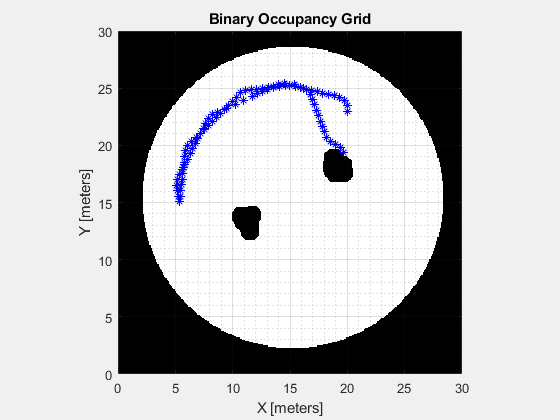

Elapsed time is 0.523749 seconds.


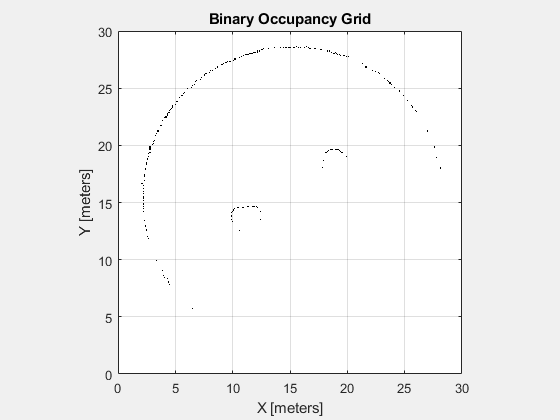

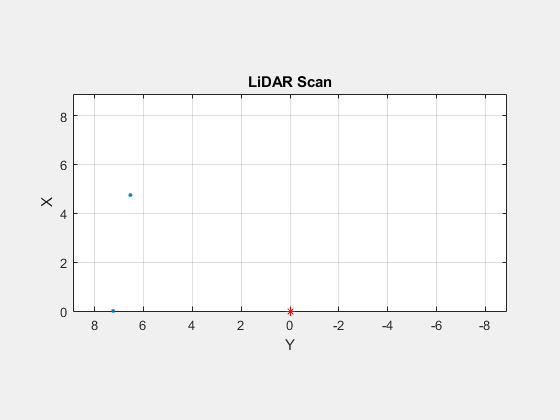

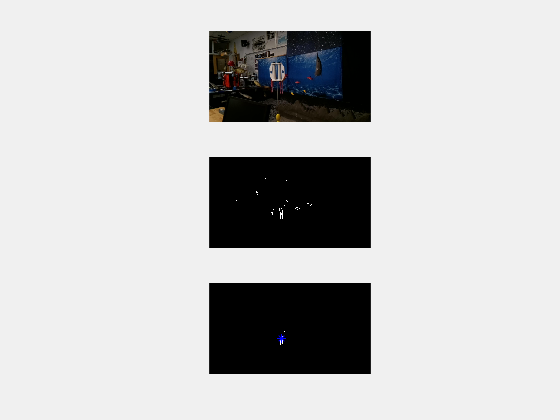

X-pixel value: 575.5430 
Y-pixel value: 443.0025 


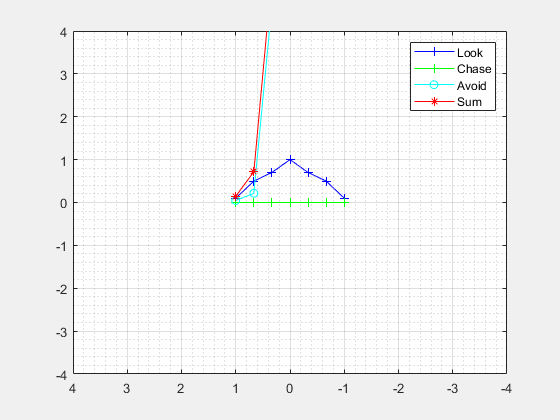

Tug crashed. All stop!


while(controlIndex < numel(t))              % Loop for number of timesteps in operating procedure
tic
    position = robotPoses(:,controlIndex)'; % gets current robot x,y, and angle
    roverLocation = position(1:2);          % extracts rover x and y from position variable
    %End the loop if rover has reached goal waypoint within tolerance
%     dist = norm(goalWayPoint' - roverLocation);    
%     if (dist < tolerance)                   % if robot has reached goal
%         break;                              % breaks out of entire control loop
%     end

    %SENSE: collects IR data from the simulated environment occupancy map 
    [ranges,angles] = SENSE(position, MapOfPoolInflated, sharpIRmap, tugSharpIRScan, localSharpIRPlot, sharpIRPod);
    image = snapshot(camera);
    [whaleSeen, targetX] = IsThereAWhale(image, narwhalCamFigure);

    %THINK: computes and stores next target position
    switch whaleSeen
        case 0      % whale NOT SEEN
            vChase = zeros(1, numWaves);
            wChase = zeros(1, numWaves);
            behaviorCycleTime = behaviorCycleTime + 1;
            if behaviorCycleTime < legTime  % Going Straight
                [tugX, tugY, vLook, wLook, robotPoses] = THINKGoStraight(robotPoses, sampleTime, diffDriveTug, controlIndex, vRef, wRef);
            else  % Turning Left or Right
                if searchDirection<0.5 % turn left
                [tugX, tugY, vLook, wLook, robotPoses] = THINKTurnLeft(robotPoses, sampleTime, diffDriveTug, controlIndex, vRef, wRef);
                else % turn right
                [tugX, tugY, vLook, wLook, robotPoses] = THINKTurnRight(robotPoses, sampleTime, diffDriveTug, controlIndex, vRef, wRef);
                end
            end
            if behaviorCycleTime > legTime + 2 % After turning
                behaviorCycleTime = 0;
                searchDirection = rand();
                legTime = rand() * 20 + 40;    % choose time to travel straight
            end
        case 1 % whale SEEN
            vLook = zeros(1, numWaves);
            wLook = zeros(1, numWaves);
            if followClock < 20 % Follow for 20 cycles
                followClock = followClock + 1;
                [tugX, tugY, vChase, wChase, robotPoses] = THINKChaseNarwhal(robotPoses, sampleTime, diffDriveTug, controlIndex, vRef, wRef, image, numWaves, targetX);
            else
                break;      % mission complete
            end
        otherwise
            beep;
            % confused. beep.
    end

    % Run Obstacle Avoidance behavior based on Sharp IR range data
    [vAvoid, wAvoid] = THINKAvoid(ranges, angles, numWaves);

    % Arbitrate behavior outputs
    [vRef, wRef] = THINKTugArbiter(vLook, wLook, vChase, wChase, vAvoid, wAvoid, brainWaves);

    % Collision detection
    crash = checkOccupancy(MapOfPoolInflated,[tugX tugY]);
    if crash
        disp("Tug crashed. All stop!");
        break;
    end
    %ACT: commands the actuators by writing on the Occupancy Map
    ACT(tugX, tugY, vRef, wRef, rudderServo, propServo, ttServo, testPool);

    controlIndex = controlIndex + 1;        % increments loop index
    waitfor(r);                             % pauses loop until sampleTime has passed
toc
end

### Clean Shutdown

To prevent systems from jamming, it is good practice to use a shutdown procedure after completing an embedded robot procedure.

To do this, set all actuators into a safe position, then release all control objects and shut down all communication paths.

% Stop program and clean up connection to Raspberry Pi in the event of a
% collision or successful mission
writePosition(rudderServo, 90);             % Exit with rudder at halfway position
writePosition(propServo, 90);               % Exit with propeller servo at halfway position. Always at 0.5!
writePosition(ttServo, 90);                 % Exit with Turntable motor controller set to stop.
clc; disp('Raspberry Pi program has ended');

Raspberry Pi program has ended


clear robotPi propServo rudderServo ttServo
beep                                        % Play a sound when actions are completed
pause(0.1);
beep
pause(0.1);
beep
pause(0.1);
beep
if crash
    beep;beep;                              % Play a total of 3 beeps in the event of a crash to introduce emotion
    keep = input("Tug crashed! Press 1 and then ENTER to keep figure windows\nor press ENTER to close them for a clean desktop.");
else
keep = input("Whale terminated. Mission success!\nPress 1 and then ENTER to keep figure windows\nor press ENTER to close them for a clean desktop.");
end
if keep == 1
    % Do nothing
else
    close all;                              % Close all figure windows for a clean desktop
end

### **Robot Functions** (store this code's local functions here)

In practice for modularity, readability and longitevity, your main robot code should be as brief as possible and the bulk of the work should be done by functions.

**Functions that are neither sense, think, nor act** (leaving room but typically scarce)

% function CONTROL_LOOP_OUTPUT(time)
%     disp('robot running, press cntrl-c to stop')
%     fprintf('The loop time is %d, \n',time)
% end

**Sense Functions **(Store all sense-related local functions here)

function [ranges, angles] = SENSE(position, mapOfTrack, blankSharpMap, fig_SharpMap, fig_localIRPlot, lidar)
% SENSE scans the reference map using the range sensor and the current pose.
% This simulates normal range readings for driving in an unknown environment.
% SENSE also updates the IR map with the range readings.
% inputs: tug position, mapOfTrack, IRMap, figure to plot global IR, figure to plot local IR, sensor name
% outputs: IR ranges and angles in local coordinate system
% CJ Hilty 2022 Rev A.

    [ranges, angles] = lidar(position, mapOfTrack);                         % Gets available ranges and angles for IR in simulated position
    scan = lidarScan(ranges,angles);                                        % Simulates IR scan
    validScan = removeInvalidData(scan,'RangeLimits',[0,lidar.Range(2)]);   % Removes values beyond the max range
    insertRay(blankSharpMap,position,validScan,lidar.Range(2));             % Plots IR scan on global map

    figure(fig_SharpMap);                                                   % Selects the global IR map
        hold on;
        show(blankSharpMap);                                                % Displays changes made
        grid on;
        grid minor;
        hold off;

    figure(fig_localIRPlot);                                                % NOTE: on the graph, positive X is forward and positive Y is left
    plot(scan);                                                             % Plots IR scan onto local map
    hold on;
    plot(0,0,'r*')                                                          % Plots robot position on local map
    plot(-1,0,'r^')                                                          % Plots robot position on local map
    plot(-2,0,'r^')                                                          % Plots robot position on local map
    hold off
end

function [whaleSeen, targetX] = IsThereAWhale(image, displayFigure)
% IsThereAWhale is a placeholder function for the Think lab student
% generated Rasp-Pi Cam code to find and track a purple narwhal

    [targetX, ~, confidence] = findWhale(image, true, displayFigure);
    whaleSeen = confidence > 0.9;
end

**Think Functions **(Store all think-related local functions here)

function [tugX, tugY, vRef, wRef, poses] = THINK(poses, diffDrive, ppControl, sampleTime, loopIndex)
% THINK gets control commands from the pure pursuit controller to drive to
% next waypoint. Calculates derivative of robot motion based on control commands.
% Inputs: Robot poses Array, diffDrive dynamics, loop sampleTime, loop index.
% Outputs: tugX, tugY, updated tug poses Array
% CJ Hilty 2022 Rev A

    %Run Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = ppControl(poses(:,loopIndex)); % Calculates velocity and angular velocity

    % Forward discrete integration that converts velocities to positions
    vel = derivative(diffDrive, poses(:,loopIndex), [vRef wRef]);
    poses(:,loopIndex + 1) = poses(:,loopIndex) + vel*sampleTime;

    % Store updated rover location for next loop
    tugX = poses(1, loopIndex + 1);
    tugY = poses(2, loopIndex + 1);
end

function [tugX, tugY, vStraight, wStraight, robotPoses] = THINKGoStraight(robotPoses, sampleTime, diffDriveTug, controlIndex, vRef, wRef)
% ThinkGoStraight behavior locks rudder at 0 (center) and
% steers Tug straight forward. Calculate derivative of robot motion
% based on control commands.
% inputs are rover poses, loop sample time, loop index
% outputs are tugX, tugY, robot poses

    % Replace pure pursuit controller with fixed velocities
    vTug = vRef;
    wTug = wRef;

    % Perform forward discrete integration step
    vel = derivative(diffDriveTug, robotPoses(:, controlIndex), [vTug, wTug]);
    robotPoses(:, controlIndex+1) = robotPoses(:, controlIndex) + vel*sampleTime;

    % Update rover location and pose
    tugX = robotPoses(1, controlIndex + 1);
    tugY = robotPoses(2, controlIndex + 1);

    % Create polled desired linear velocity
    vStraight = [0 0.5 1 2 1 0.5 0];
    wStraight = [0.1 0.5 0.7 1 0.7 0.5 0.1];
end

function [tugX, tugY, vTurn, wTurn, robotPoses] = THINKTurnLeft(robotPoses, sampleTime, diffDriveTug, controlIndex, vRef, wRef)
% THINKTurnLeft behavior locks rudder at fixed rudder position and
% steers tug in a tight left turn. Calculate derivative of robot motion
% based on control commands.
% inputs are rover poses, loop sample time, loop index
% outputs are tugX, tugY, robot poses

    vTug = vRef;
    wTug = wRef;

    % Perform forward discrete integration step
    vel = derivative(diffDriveTug, robotPoses(:, controlIndex), [vTug, wTug]);
    robotPoses(:, controlIndex + 1) = robotPoses(:, controlIndex) + vel*sampleTime;

    % Update rover pose
    tugX = robotPoses(1, controlIndex+1);
    tugY = robotPoses(2, controlIndex+1);

    % Determine brainwaves
    vTurn = [1.8 2 1.8 1.7 0 0 0];
    wTurn = [1.1 1 0.9 0.8 0 0 0];
end

function [tugX, tugY, vTurn, wTurn, robotPoses] = THINKTurnRight(robotPoses, sampleTime, diffDriveTug, controlIndex, vRef, wRef)
% THINKTurnLeft behavior locks rudder at fixed rudder position and
% steers tug in a tight right turn. It also calculates robot motion
% based on control commands.
% inputs are tug poses, loop sample time, loop index.
% outputs are tugX, tugY, robot poses

    vTug = vRef;
    wTug = wRef;

    % Perform forward discrete integration step
    vel = derivative(diffDriveTug, robotPoses(:, controlIndex), [vTug, wTug]);
    robotPoses(:, controlIndex + 1) = robotPoses(:, controlIndex) + vel*sampleTime;

    % Update rover pose
    tugX = robotPoses(1, controlIndex+1);
    tugY = robotPoses(2, controlIndex+1);

    % Determine brainwaves
    vTurn = [0 0 0 1.7 1.8 2 1.8];
    wTurn = [0 0 0 0.8 0.9 1 1.1];
    
end

function [vAvoid, wAvoid] = THINKAvoid(ranges, ~, numWaves)
% THINKAvoid behavior takes in the ranges from the Tugs Sharp IR array and
% converts them into a set of polled linear and rotational velocity
% designed to avoid crashing into perceived obstacles
    
    starboardSensors = ranges(1:3);                     % Sharp IRs pointing right
    portSensors = ranges(4:6);                          % Sharp IRS pointing left
    middleSensor = (ranges(3) + ranges(4)) / 2;         % Make up a virtual middle sensor
    s1 = vertcat(starboardSensors, middleSensor);    % add virtual middle to left array
    sensorArray = vertcat(s1, portSensors);             % add right array
    TF = isnan(sensorArray);                            % find any NaN values
    sensorArray(TF) = 30;                               % replace NAN values
    sensorArray = (sensorArray - 7) / 5;                % Scale down

    % Travel opposite direction of obstacle array, set motor to zero
    wAvoid = sensorArray';
    wAvoid = flip(wAvoid);
    vAvoid = zeros(1, numWaves);

%   OBJECT_THRESHOLD = 7;
%     for iScanTransform = 1:7
%         if sensorArray(iScanTransform) < OBJECT_THRESHOLD
%             sensorArray(iScanTransform) = -3;             % If close to object, don't turn this way
%         else
%             sensorArray(iScanTransform) = 2;                % Otherwise, can turn this way
%         end
%     end

end

function [tugX, tugY, vWhale, wWhale, robotPoses] = THINKChaseNarwhal(robotPoses, sampleTime, diffDriveTug, controlIndex, vRef, wRef, image, numWaves, targetX)
    % THINKChaseNarwhal takes in an image and returns the brainwaves to
    % chase the narwhal

    minX = 0;
    maxX = size(image, 2);
    segmentRanges = linspace(minX, maxX, numWaves + 1);    % Create the segment ranges - 7 ranges means 8 numbers
    minSegments = segmentRanges(1:end-1);
    maxSegments = segmentRanges(2:end);
    midSegments = (minSegments + maxSegments) / 2;

    % Make brainwaves
    vWhale = zeros(1, numWaves);
    wWhale = -abs(targetX - midSegments) / maxX * 2;       % Prefer being close. Negate so close is higher numbers

    % Calculate next robot position
    vTug = vRef;
    wTug = wRef;

    % Perform forward discrete integration step
    vel = derivative(diffDriveTug, robotPoses(:, controlIndex), [vTug, wTug]);
    robotPoses(:, controlIndex + 1) = robotPoses(:, controlIndex) + vel*sampleTime;

    % Update rover pose
    tugX = robotPoses(1, controlIndex+1);
    tugY = robotPoses(2, controlIndex+1);
end

function [targetX, targetY, confidence] = findWhale(frame, displayFigure, camFigure)
    % findWhale chooses the largest continuous segment of camera input that
    % contains the hue, saturation, value parameters that best captured
    % only the target whale (pink) against a blue background on 15 Feb 2022.
    % Inputs are image frame and optional boolean to display image.
    % Tyler Ewald and CJ Hilty, 2022. Rev. A.
    
    % Extract the regions of the image that correspond to the whale
    % Based on the colors we selected for the mask generator
    [BW, ~] = createMask(frame); %calls auto-generated function
    
    % Create labels for the masked black-and-white image for every continuous region
    % L is a matrix of the original snapshot size that has a different number
    % for each chunk the bwlabel function identifies in the image, or 0 if not
    % part of a region. Values will range from 0 to num.
    [L, num] = bwlabel(BW,8); 
    
    if num>0
        % Compute size of each continuous region, and find the largest region
        % Compares each of every 1280*720 entries (921600 pixels) in L
        % to the values 1:num, which turns that into a 921600*num matrix, then sums each column
        count_pixels_per_obj = sum(L(:)==(1:num)); 
        
        % Create new mask that only contains largest region
        [blob_size,ind] = max(count_pixels_per_obj);
        biggest_blob = (L==ind);
        
        % Compute center of this region
        s = regionprops(biggest_blob, 'centroid');
        centroids = cat(1,s.Centroid);

        % Assign center of largest region to our output variables
        targetX = centroids(1);
        targetY = centroids(2);

        % Set confidence interval based on absolute narwhal size in frame
        minPixels = numel(frame) / 3 * 0.01;    % 1 percent of pixels (divided by 3 channels) in original frame
        if blob_size > minPixels
            confidence = 1; % Reaches max confidence once ~1% of the frame is filled
        else
            confidence = blob_size/(minPixels);
        end
        
        % Display the results
        if displayFigure
            figure(camFigure);
            % Display original image
            subplot(311), imshow(frame);
            % Display color-masked image
            subplot(312), imshow(BW);
            % Display largest blob with center marked
            subplot(313), imshow(biggest_blob); 
            hold on; plot(centroids(:,1),centroids(:,2),'b*'); hold off;
        
            fprintf(['X-pixel value: %.4f \n'], targetX);
            fprintf(['Y-pixel value: %.4f \n'], targetY);
        end
    else % If no pixels matching the Narwhal-colored mask are found
        targetX = 0;
        targetY = 0;
        confidence = 0;
    end
end


function [vRef,wRef] = THINKTugArbiter(vLook, wLook, vChase, wChase, vAvoid, wAvoid, brainWaves)
%THINKTugArbiter takes in the desired outputs of the Robot Tugs
%many behaviors, merges just the headings into a single ridder position
%Speed arbitation can be added by student teams for better performance

    numWaves = length(vLook);               % how many brain waves
    turnSpeeds = linspace(1, -1, numWaves); %create a vector of possible turn rates
    velSpeeds = linspace(0, 2, numWaves);   % create a vector of possible forward velocities
    figure(brainWaves)                      % go to brain waves figure
    %clf
    plot(turnSpeeds,wLook,'b-+');           %plot straight waveform
    ax = gca;                               %Assign current plot to a variable to perform actions to the plot
    ax.XDir = 'reverse';
    axis([-4 4 -4 4]);
    grid on;
    grid minor;
    hold on
    plot(turnSpeeds,wChase, 'g-+');         %plot turn waveform
    plot(turnSpeeds,wAvoid,'c-o');          %plot avoid waveform

    vSumOfWaves = vLook + vChase + vAvoid;  % sum of velocity waveforms
    wSumOfWaves = wLook + wChase +  wAvoid; % sum of rotational velocity waveforms
    plot(turnSpeeds,wSumOfWaves,'r-*');     % plot sum of rot waveform
    legend('Look', 'Chase', 'Avoid', 'Sum') % label plot
    hold off
    [~, vMaxIndex] = max(vSumOfWaves);      % Find peak of summed waveform
    [~, wMaxIndex] = max(wSumOfWaves);      % find peak of summed waveform

    vRef = velSpeeds(vMaxIndex);            %set speed based on peak of votes
    wRef = turnSpeeds(wMaxIndex);           %set tug turn rate based on peak of behavior voting curve
end


**Act Functions **(Store all act-related local functions here)

function ACT(tugX, tugY, vRef, wRef, rudderServo, propServo, ttServo, fig_testPool)
% ACT plots the updated robot pose based on the results of THINK.
% inputs: Robot's X and Y coordinates, figure to plot robot in.
% no outputs.
% CJ Hilty 2022 Rev A

    figure(fig_testPool)
    hold on;
    plot(tugX, tugY, 'b*');         % Plot tug position in test pool
    hold off;

    % Drive tug hardware servo motors
    rudderAngle = wRef*15;          % convert angular wRef to rudder degrees
    propSpeed = vRef;               % set veriable to pass into act function for clarity
    TugServoControl_RevB(rudderServo, propServo, ttServo, rudderAngle, propSpeed);          % Assign this to an unused output if it does not work
end